% Note - incomplete

clc % clear command window
clear all % clear workspace

1. Supply path to the toolkit's "model_code" directory to "cfg" structure, and add the "common" subfolder to the MATLAB path. Also specify the general directory where results will be saved. 

% Add paths to relevant functions
cfg.model_dir = '/Shared/boeslab/Users/jcgriffis/mlsm_code_repo/model_code'; % path to toolkit
addpath(fullfile(cfg.model_dir, 'common')); % add common folder to path

% Specify output directory (Note - output folders for specific analyses will be created in this directory)
out_dir = '/Shared/boeslab/Users/jcgriffis/toolkit_paper_analyses/tutorial_results';

2. To perform a lesion-mapping/lesion-modeling analysis, specify that the modality is "lesion", and supply a path to a brain mask that is 

co-registered to the same template as your lesion data and that has the same image and voxel dimensions as your lesion data.

% Specify data modality and supply brain mask
cfg.modality = 'lesion'; % predictor modality - 'lesion' or 'other' 
cfg.mask_path = fullfile('/Shared/boeslab/Data/Lesion/Iowa/Registry/derivedData/LesionQuantificationToolkit/Chronic/Yeo7200/Lesion_3mm/mask/brain_mask.nii'); % path to brain mask

3. Specify general modeling options.

- cfg.model_spec - the type of model you want to fit. Regression options: 'plsr', 'ridge', 'linsvr', and 'kernsvr'. Classification options: 'pls_da', 'logistic_ridge', 'linsvc', 'kernsvc'. Mass-Univariate options: 'bmunz', 'municorr', 'ttest'. 

- cfg.fit_explanatory_model - flag indicating whether you want to fit a model to the full dataset to test significance of model coefficients. For inferential (e.g., lesion-symptom mapping) analyses, turn this on. Note that the model is explanatory, not predictive. 

- cfg.optimize_hyperparams - flag indicating whether you want to use cross-validation to optimize model hyper-parameters. For multivariate models, this is recommended.

- cfg.cross_validation - flag indicating whether you want to use cross-validation to estimate predictive performance and out-of-sample generalization. If hyper-parameter optimization is selected, then this will perform nested cross-validation. For predictive analyses, turn this on. Note that significance testing is not performed on model coefficients/maps. 

- cfg.bootstrap - flag indicating whether you want to use bootstrapping to estimate statistical significance of model coefficients and/or to estimate confidence intervals for multivariate explanatory models. Recommended if fitting multivariate explanatory model.

- cfg.permutation - flag indicating whether you want to use permutation testing to estimate statistical significance of model fit and/or model coefficients. Recommended.

These options will be used to initialize an analysis with default parameters for the selected options by supplying the cfg structure as an input to the function get_default_model_cfg(), which automatically populates the cfg structure with default settings for the specified modeling options, and returns the populated cfg structure. 

% Specify general modeling options
cfg.model_spec = 'ttest'; % mass univariate correlations
cfg.fit_explanatory_model = 1; % run explanatory lesion-symptom mapping analysis
cfg.permutation = 1; % use permutation testing for significance testing 

% Initialize cfg file with default settings given general modeling options
cfg = get_default_model_cfg(cfg); 

Mass univariate analysis selected - hyper-parameter optimization will not be performed
Mass univariate analysis selected - cross-validation will not be performed
Mass univariate analysis selected - bootstrapping is disabled
cfg.jackknife field is empty; setting to 0 with default settings
Analysis type is lesion - setting defaults


4. Specify paths to behavioral and lesion data, and load and format data into predictor matrix and response array. The behavioral CSV file should include a "study_id" column containing patient IDs and a second column containing behavioal scores. Also specify the path to the directory containing the lesion images. Lesion images for all patients should be in the same folder. Note: IDs in "study_id" column must match file prefixes for lesion data - e.g., if the "study_id" for patient 1 is "0001", then their lesion file should be "0001.nii.gz". There must be a lesion image for all subjects with non-missing behavioral data.

The function get_and_format_lesion_data() adds several fields to the cfg structure: 

- cfg.X - subject-by-voxel lesion predictor matrix 

- cfg.lvol - subject-by-1 array of lesion volumes

- cfg.Y - subject-by-1 array of behavioral scores

- cfg.include_subs - string array of subject IDs that had non-missing behavioral data and that were included in the analysis.

% Specify path to CSV containing study IDs and behavioral scores
beh_csv = readtable('/Shared/boeslab/Users/jcgriffis/toolkit_paper_analyses/behavior/test_data.csv'); % read in CSV file as table
id_col = 'study_id'; % name of column containing 4-digit IDs
beh_col = 'mae_token'; % name of column containing behavior of interest

% Specify lesion directory and indicate whether patients are registry patients
lesion_dir = '/Shared/boeslab/Data/Lesion/Iowa/Registry/derivedData/LesionQuantificationToolkit/Chronic/Yeo7200/Lesion_3mm'; % directory containing lesion images
registry_flag = 1; % CSV contains numeric registry IDs (i.e., '0's need to be appended for subjects < 1000)

% Get formatted lesion matrix, behavioral data, subject IDs, and mask volume/header and in-mask indices
% Note: outputs are stored as fields in cfg structure 
cfg = get_and_format_lesion_data(beh_csv, id_col, beh_col, registry_flag, lesion_dir, cfg);

All subjects with behavioral data have lesion files, N=282 patients will be included


5. Specify the specific folder where analysis results should be saved. Note - if the output folder specified in cfg.out_dir doesn't exist, it will be created automatically once the analysis is run.

% Specify output directory
cfg.out_dir = fullfile(out_dir, [cfg.model_spec '_' beh_col '_lvr']); % folder will be in the original out_dir, in a folder named "plsr_token"

6. Modify any default settings as relevant to the analysis. Here, we increase the frequency threshold from the default (4) to 10, assign lesion volume as a confound for regression from the outcome variable, turn on the continuous FWE procedure for whole-brain permutation testing, and turn on coefficient-level permutation testing. See the function get_default_model_cfg() for all default parameter values. 

% Customize analysis parameters

% T-tests
cfg.var_type = 'unequal'; % We will assume unequal variances between groups at each voxel ('equal' assumes equal variances between groups at each voxel)
cfg.group_var = 'X'; % Group patients based on lesion status, and compare Y between groups. If 'Y', then the outcome will be the grouping variable, and each feature in X will be compared between groups (requires continuous features)

% Lesion-mapping
cfg.freq_thresh = 10; % only include voxels that are lesioned in at least 10 patients
cfg.confounds = cfg.lvol; % Regress lesion volume out of the outcome variable prior to analysis

% Statistical significance testing 
cfg.perm.n_perm = 1000; % permutation iterations
cfg.perm.coeff_cfwe = 1; % get cFWE whole-brain corrected p-values
cfg.perm.coeff_p = 1; % get voxel-wise permutation p-values
cfg.perm.coeff_fdr = 1; % perform FDR correction on voxel-wise permutation p-values 
cfg.perm.coeff_fwe = 1; % perform FWE correction on voxel-wise permutation p-values 
cfg.perm.write_perm_images = 1; % Write permutation result images

7. Supply the fully-specified cfg structure as input to the function fit_and_evaluate_model(), which executes the modeling analysis specified in the cfg structure. This returns a new structure, model_results, which contains the results of the modeling analysis along with the original cfg file (as a sub-structure) for reproducibility. This structure is saved by default in the folder specified by cfg.out_dir. If cross-validation was performed, a second structure named cv_results, which contains the results of the cross-validation analyses, will be saved in the file "cv_results.mat" within the output directory specified by cfg.out_dir. 

% fit model with CV hyperparameter optimization and selected significance testing
[model_results] = fit_and_evaluate_model(cfg);

Trimming data to retain columns with at least 10 observations greater than or equal to 1
14 subjects have no predictor data after trimming...removing from analysis
Regressing confounds out of Y...
Confound model explained 26.26% variance in Y.
Continuing analysis with Y residuals as target variable
Running permutation analysis: 1
Running permutation analysis: 2
Running permutation analysis: 3
Running permutation analysis: 4
Running permutation analysis: 5
Running permutation analysis: 6
Running permutation analysis: 7
Running permutation analysis: 8
Running permutation analysis: 9
Running permutation analysis: 10
Running permutation analysis: 11
Running permutation analysis: 12
Running permutation analysis: 13
Running permutation analysis: 14
Running permutation analysis: 15
Running permutation analysis: 16
Running permutation analysis: 17
Running permutation analysis: 18
Running permutation analysis: 19
Running permutation analysis: 20
Running permutation analysis: 21
Running permutat

8. View model results structure to evaluate model performance measures. The different fields contain different details about analysis parameters, data, and results.

- has_data - logical array of length n_subjects with values of 1 for all patients that were included in the analysis. Some patients may have been dropped due to not having any data after removing voxels that met the minimum damage threshold, and this can be used to identify which patients were dropped and which patients were retained for the analysis. 

- r2_confound - R-squared for the explanatory confound model fit to the full dataset 

- coeff - t-statistics

- coeff_pvals - parametric 

- coeff_vfwe_pvals - family-wise error corrected parametric p-values for t-statistics in coeff

- coeff_vfdr_pvals - false discovery rate corrected parametric p-values for Peasrson correlations in coeff

- tstat - t-statistics for Pearson correlations in coeff

- obs_y - observed behavioral scores, in this case standardized. Note that it has 268 rows, while the original input had 282 rows, indicating 14 patients were removed due to no longer having any lesion data after trimming columns with insufficient observations. The patients that were removed from the original cfg.Y will have values of 0 in model_results.has_data.

- perm - subfield containing results from permutation testing

- X - final predictor matrix after trimming columns with insufficient data, in this case transformed by the DTLVC method. Note that it has 268 rows, while the original input had 282 rows, indicating 14 patients were removed due to no longer having any lesion data after trimming columns with insufficient observations. The patients that were removed from the original cfg.X will have values of 0 in model_results.has_data.

- X_ind - indices mapping the columns in the final predictor matrix model_results.X to the colulmns in the original predictor matrix cfg.X, i.e., the columns included in model_results.X are given by: model_results.X = cfg.X(model_results.X_ind) 

- cfg - the cfg structure containing analysis parameters and details for reproducibility

% View contents of model_results structure
model_results

model_results = struct with fields:
            has_data: [282×1 logical]
         r2_confound: 0.2626
      coeff_confound: [2×1 double]
    coeff_vfdr_pvals: [13786×1 double]
    coeff_vfwe_pvals: [13786×1 double]
         coeff_pvals: [13786×1 double]
               tstat: [13786×1 double]
                perm: [1×1 struct]
               obs_y: [268×1 double]
                   X: [268×13786 single]
               X_ind: [13786×1 double]
            rng_seed: {[0]  'twister'}
                 cfg: [1×1 struct]
        methods_text: 'Data were analyzed using mass-univariate independent samples t-tests. Only predictors with at least 10 non-zero observations with absolute values greater than 1 were included in the analysis. After excluding observations with no data for any included predictors, N=268 observations were included in the analysis. Confound regression was performed to remove variance associated with user-defined nuisance regressors from the outcome variable in the training 

By accessing fields in the model_results structure, you can evaluate the output of the mass-univariate analysis. Here, we print out the number of supra-threshold voxels at each cFWE threshold along with the maximum lesion-behavior correlation.

% Evaluate how many voxels survive at each cFWE voxel count threshold
cfwe_fields = fieldnames(model_results.perm.cfwe);
for i = 1:length(cfwe_fields)
    crit_t = model_results.perm.cfwe.(cfwe_fields{i});
    n_survive.(cfwe_fields{i})(1,2) = numel(find(model_results.tstat >= crit_t));
    n_survive.(cfwe_fields{i})(1,1) = crit_t;  
end
% Display critical t-statistics for each cFWE voxel count threshold along with the number of surviving voxels
disp(n_survive);

       crit_val_1: [6.4956 0]
      crit_val_10: [5.8332 0]
      crit_val_50: [5.1819 0]
     crit_val_100: [4.8070 0]
     crit_val_500: [3.4221 0]
    crit_val_1000: [2.7726 0]



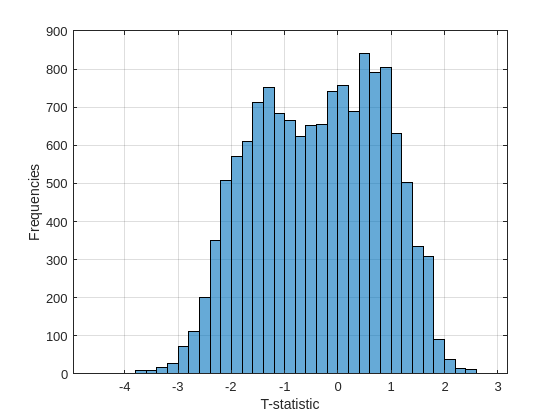

% Plot histogram of lesion-behavior correlations
histogram(model_results.tstat);
grid on; xlabel('T-statistic'); ylabel('Frequencies')

9. Save explanatory model coefficients as NIFTI images (i.e., as lesion-symptom maps). NIFTI images containing model coefficients will be saved in the output directory specified by cfg.out_dir. If bootstrapping and/or permutation testing was performed for model weights, then result images will be saved into sub-folders named "Bootstrap_Result_Images" and "Permutation_Result_Images", respectively. 

% Map model coefficients back to the in-brain voxels of the 3D MNI volume using MATLAB NIFTI I/O functions
disp('Saving beta weight maps as NIFTI images...');

Saving beta weight maps as NIFTI images...


write_model_weight_maps(model_results);
disp('Done')

Done
